imgFile = "train-images-idx3-ubyte";
labelFile = "train-labels-idx1-ubyte";
readDigits = 100;
offset = 0;

pwd

ans = 'D:\Uni\FIB-VC\Práctica 2\data'

[imgs labels] = readMNIST(imgFile, labelFile, readDigits, offset)

imgs = imgs(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0118    0.0706    0.0706    0.0706    0.4941    0.5333    0.6863    0.1020    0.6510    1.0000    0.9686    0.4980
         0         0         0         0    0.1176    0.1412    0.3686    0.6039    0.6667    0.9922    0.9922    0.9922    0.9922    0.9922    0.8824    0.6745    0.9922    0.9490    0.7647    0.2510
         0         0         0    0.1922    0.9333    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9922    0.9843    0.3647    0.3216    0.3216    0.2196    0.1529         0
         0         0         0    0.0706    0.8588    0.9922    0.9922    0.9922    0.9922    0.9922    0.7765    0.7137    0.9686    0.9451         0         0         0    

labels =      5
     0
     4
     1
     9
     2
     1
     3
     1
     4



img = imgs(:, :, 50); % 1
img = imresize(img, [50, 50]);

imshow(img)

[centers, radii, metric] = imfindcircles(img, [10 50])

centers =    25.8991   35.6374


radii = 12.7768

metric = 0.1867

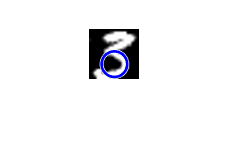


viscircles(centers, radii,'EdgeColor','b');


edges = edge(img,'canny')

edges = 20×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1   1   1   1   0   0   1   1   1   1   0   0   0
   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   1   1   0   0
   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   1   1   0   0
   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   1   1   0   0   0
   0   0   0   0   0   0   0   1   0   0   0   0   0   1   1   1   0   0   0   0
   0   0   0   0   0   0   1   0   0   0   0   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   1   1   0   0   0   0   0   1   0   0   0   0   0   0


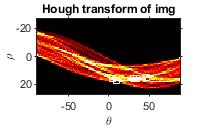


[H,T,R] = hough(edges);

imshow(imadjust(rescale(H)),'XData',T,'YData',R, 'InitialMagnification','fit'); title('Hough transform of img'); xlabel('\theta'), ylabel('\rho'); axis on, axis normal, hold on; colormap(gca,hot);

P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:)))); x = T(P(:,2)); y = R(P(:,1)); plot(x,y,'s','color','white');

P

P =     44    96
    45   100
    44   121
    44   125
    43   138


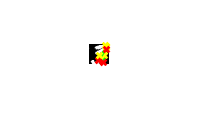

lines = houghlines(edges,T,R,P,'FillGap',5,'MinLength',7); figure, imshow(img), hold on; max_len = 0; 
for k = 1:length(lines)    
    xy = [lines(k).point1; lines(k).point2];    
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');     
    % Plot beginnings and ends of lines    
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');    
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');     
    % Determine the endpoints of the longest line segment    
    len = norm(lines(k).point1 - lines(k).point2);    
    if ( len > max_len)       
        max_len = len;       
        xy_long = xy;    
    end 
end